Here we are, we will compare the cross-coupling effect at fully-aligned condition.

The inductance matrices and power stayed constant, we only change the cross-coupling from -0.04

to -0.16

Full aligned (FA) data are loaded below.  Data is in the directory of 'Y:\Github\Studies\WPT\Testler\Makale'

load('FA150kHz_Coupled.mat');
load('FA150kHz_decoupled.mat');
IinVinFA=IinVin;
IinFA=Iin;
Is2FA=Is2;
Is1FA=Is1;

FA data comprise from input voltage and current and receiver side currents.

FA input voltage and current comparison

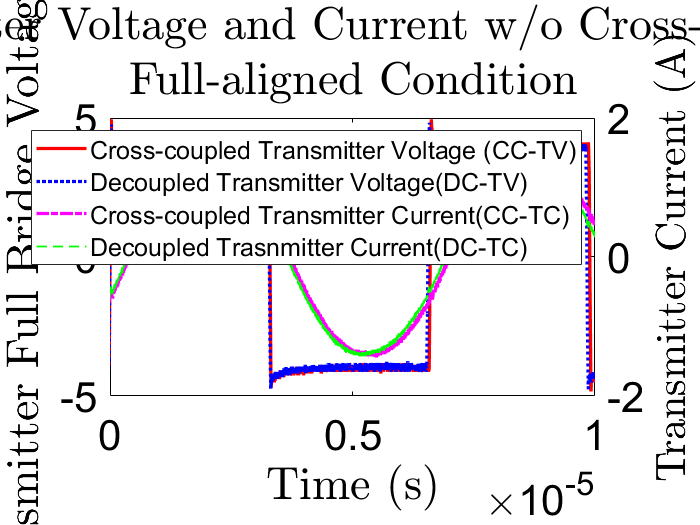

figure();
set(gca,'fontSize',25)
yyaxis left;
plot(timeTx,FA150Vin,'Color','r','LineWidth',2)
hold on;
plot(timeTx,IinVinFA,'Color','b','LineStyle',':','LineWidth',2)
ylabel('Transmitter Full Bridge Voltage (V)','FontWeight','bold' ...
    ,'Interpreter','latex','FontSize',25)
xlabel('Time (s)','Color','k','FontWeight','bold' ...
    ,'Interpreter','latex','FontSize',25)
hold on;
set(gca,'YColor','k')
yyaxis right;
plot(timeTx,FA150Iin,'Color','m','LineStyle','-.','LineWidth',2)
hold on;
plot(timeTx,IinFA,'Color','g','LineStyle','--','LineWidth',1)
ylabel('Transmitter Current (A)','FontWeight','bold' ...
    ,'Interpreter','latex','FontSize',25)
xlabel('Time (s)','Color','k','FontWeight','bold' ...
    ,'Interpreter','latex','FontSize',25)
xlim([-0e-5,1e-5]);

title({'Tansmitter Voltage and Current w/o Cross-Coupling','Full-aligned Condition'},'Color','k','FontWeight','bold' ...
    ,'Interpreter','latex','FontSize',25)
set(gca,'XColor','k')
set(gca,'YColor','k')
legend({'Cross-coupled Transmitter Voltage (CC-TV)', ...
    'Decoupled Transmitter Voltage(DC-TV)', ... 
    'Cross-coupled Transmitter Current(CC-TC)', ...
    'Decoupled Trasnmitter Current(DC-TC)'},'FontSize',15);

FA receiver side current

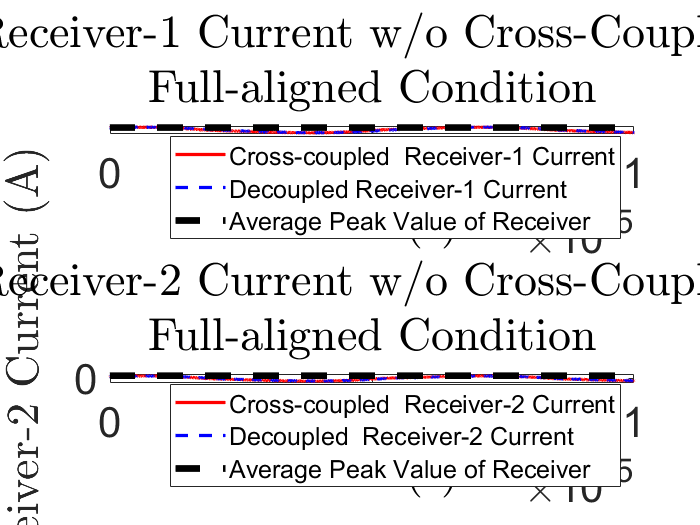

figure();
subplot(2,1,1);

plot(timeTx,FA150Is1,'Color','r','LineWidth',2)
hold on;
plot(timeTx,Is2FA,'Color','b','LineStyle','--','LineWidth',2)
ylabel('Receiver-1 Current (A)','FontWeight','bold' ...
    ,'Interpreter','latex','FontSize',35)
xlabel('Time (s)','Color','k','FontWeight','bold' ...
    ,'Interpreter','latex','FontSize',35)
xlim([-1e-5,1e-5]);
hold on;
average=0.62;
plot(timeTx,average*ones(size(timeTx)), ...
    'Color','k','LineStyle','--','LineWidth',4)
legend({'Cross-coupled  Receiver-1 Current ', ...
    'Decoupled Receiver-1 Current','Average Peak Value of Receiver' },'FontSize',15);
xlim([-0e-5,1e-5]);
ylim([-1 1])
title({'Receiver-1 Current w/o Cross-Coupling','Full-aligned Condition'},'Color','k','FontWeight','bold' ...
    ,'Interpreter','latex','FontSize',35)
set(gca,'FontSize',25)

subplot(2,1,2);
plot(timeTx,FA150Is2,'Color','r','LineWidth',2)
hold on;
plot(timeTx,Is1FA,'Color','b','LineStyle','--','LineWidth',2)
hold on;
average=0.62;
plot(timeTx,average*ones(size(timeTx)), ...
    'Color','k','LineStyle','--','LineWidth',4)
ylabel('Input Square Wave Voltage (V)')
xlabel('time')
xlim([-1e-5,1e-5]);
ylabel('Receiver-2 Current (A)','FontWeight','bold' ...
    ,'Interpreter','latex','FontSize',35)
xlabel('Time (s)','Color','k','FontWeight','bold' ...
    ,'Interpreter','latex','FontSize',35)
legend({'Cross-coupled  Receiver-2 Current ', ...
    'Decoupled  Receiver-2 Current','Average Peak Value of Receiver'...
    },'FontSize',15);
xlim([-0e-5,1e-5]);
ylim([-1 1])
title({'Receiver-2 Current w/o Cross-Coupling','Full-aligned Condition'},'Color','k','FontWeight','bold' ...
    ,'Interpreter','latex','FontSize',35)
set(gca,'FontSize',25)

Clear Full-aligned data and add Misaligned data

load('MA150kHz_Coupled.mat');
load('MA150kHz_decoupled.mat');

IinVinMA=IinVin;
IinMA=Iin;
Is2MA=Is2;
Is1MA=Is1;

MA input voltage and current

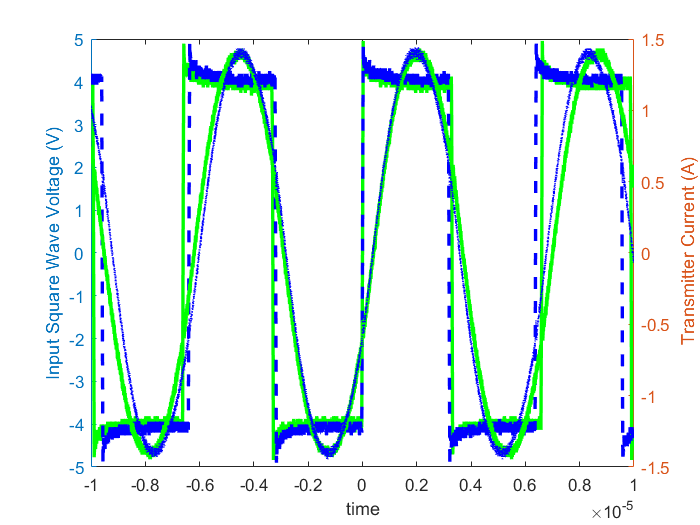

figure();
yyaxis left;
plot(timeTx,FA150Vin,'Color','g','LineWidth',2)
hold on;
plot(timeTx,IinVinMA,'Color','b','LineStyle','--','LineWidth',2)
ylabel('Input Square Wave Voltage (V)')
xlabel('time')
hold on;
yyaxis right;
plot(timeTx,FA150Iin,'Color','g','LineWidth',2)
hold on;
plot(timeTx,IinMA,'Color','b','LineStyle',':','LineWidth',1)
ylabel(' Transmitter Current (A)')
xlabel('time');
xlim([-1e-5,1e-5]);

%%set(gca,'fontSize',18)

MA receiver side current

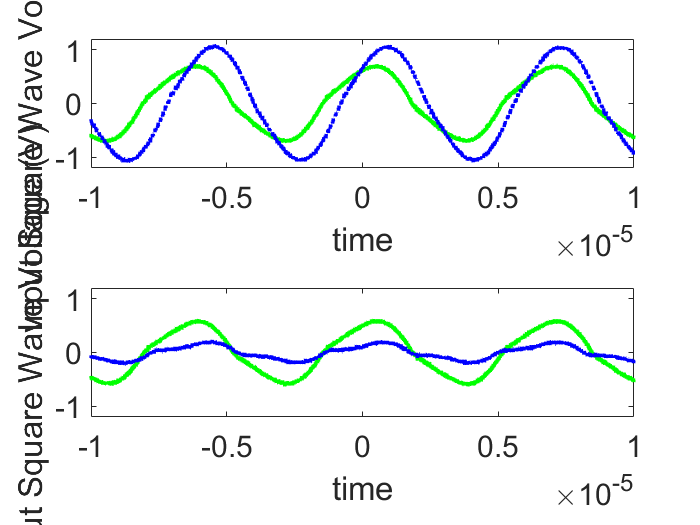

figure();
subplot(2,1,1);

plot(timeTx,FA150Is1,'Color','g','LineWidth',2)
hold on;
plot(timeTx,Is2MA,'Color','b','LineStyle','--','LineWidth',2)
ylabel('Input Square Wave Voltage (V)')
xlabel('time')
xlim([-1e-5,1e-5]);
ylim([-1.2 1.2]);
set(gca,'fontSize',18)

subplot(2,1,2);
plot(timeTx,FA150Is2,'Color','g','LineWidth',2)
hold on;
plot(timeTx,Is1MA,'Color','b','LineStyle','--','LineWidth',2)
ylabel('Input Square Wave Voltage (V)')
xlabel('time')
xlim([-1e-5,1e-5]);
ylim([-1.2 1.2]);
set(gca,'fontSize',18)

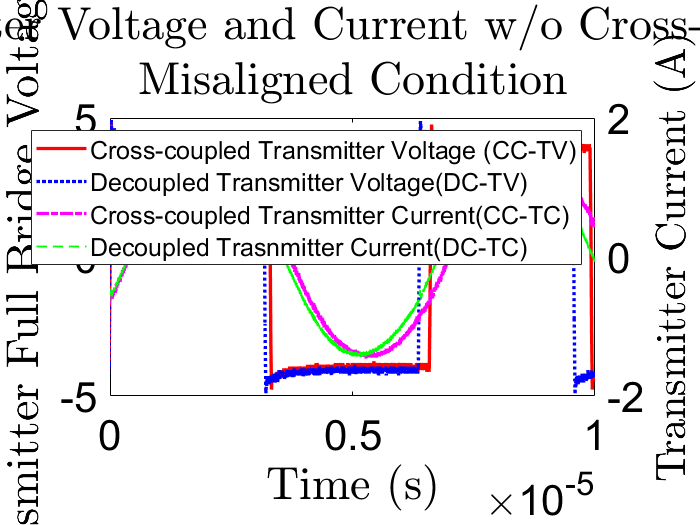

figure();
set(gca,'fontSize',25)
yyaxis left;
plot(timeTx,MA150Vin,'Color','r','LineWidth',2)
hold on;
plot(timeTx,IinVinMA,'Color','b','LineStyle',':','LineWidth',2)
ylabel('Transmitter Full Bridge Voltage (V)','FontWeight','bold' ...
    ,'Interpreter','latex','FontSize',25)
xlabel('Time (s)','Color','k','FontWeight','bold' ...
    ,'Interpreter','latex','FontSize',25)
hold on;
set(gca,'YColor','k')
yyaxis right;
plot(timeTx,MA150Iin,'Color','m','LineStyle','-.','LineWidth',2)
hold on;
plot(timeTx,IinMA,'Color','g','LineStyle','--','LineWidth',1)
ylabel('Transmitter Current (A)','FontWeight','bold' ...
    ,'Interpreter','latex','FontSize',25)
xlabel('Time (s)','Color','k','FontWeight','bold' ...
    ,'Interpreter','latex','FontSize',25)
xlim([-0e-5,1e-5]);

title({'Tansmitter Voltage and Current w/o Cross-Coupling','Misaligned Condition'},'Color','k','FontWeight','bold' ...
    ,'Interpreter','latex','FontSize',25)
set(gca,'XColor','k')
set(gca,'YColor','k')
legend({'Cross-coupled Transmitter Voltage (CC-TV)', ...
    'Decoupled Transmitter Voltage(DC-TV)', ... 
    'Cross-coupled Transmitter Current(CC-TC)', ...
    'Decoupled Trasnmitter Current(DC-TC)'},'FontSize',15);